# On the Feasibility of Throwing Objects into Orbit

### By Ari Porad and Max Stopyra

### Modeling and Simulation of the Physical World, Project 3, December 10th, 2020

## Question (Design)

What is the lowest velocity required to throw an object into Low Earth Orbit (LEO) from the surface of the Earth?  

This is an interesting question because it investigates the feasibility of small scale space launches from the surface of the Earth. By asking this question we will not only learn what the optimal velocity needed to launch and temporarily keep an object in Low Earth Orbit is, but how an object's launch velocity affects it’s orbital trajectory. 

load constants.mat;
velocities = 0:10:9000;
timespan = [0 10^7];
[max_heights, min_heights] = sweep(velocities, timespan);

## Model

In order to answer our question we modeled the position and velocity over time of an object launched into space given the acceleration of gravity acting on the object and its initial velocity.

### Assumptions

As with all models, we made some assumptions. Here are some of them:

- The object is launched from 1 meter above sea level in a direction tangent to the surface of the Earth. This was a good assumption because it simplified our model without fundementally altering the nature of our results.

- We did not account for air resistance or drag force which was good because it didn’t change our conclusion and it greatly simplified our model.

- We assumed the object was passive and didn’t model a hohmann transfer. This was a good assumption because it simplified our model and didn't affect our conclusion.

- The Earth in our model is perfectly circular and uniformly dense, which is a good assumption because it simplifies our model and allows us to focus more on the object in orbit

- The object thrown into orbit is 5 kg and uniformly dense. This was a good assumption because it made modeling the system easier and set specifications for the object and allowed us to focus more on modeling the temporary orbit of the object.

- We didn’t account for the orbital mechanics of the Earth (relative to the Sun, etc.). This was a good assumption because it made modeling the trajectory and of our object easier, without being significant to our conclusions.

### Iteration & Improvement

We itteratively 

### Schematic & Free Body Diagram

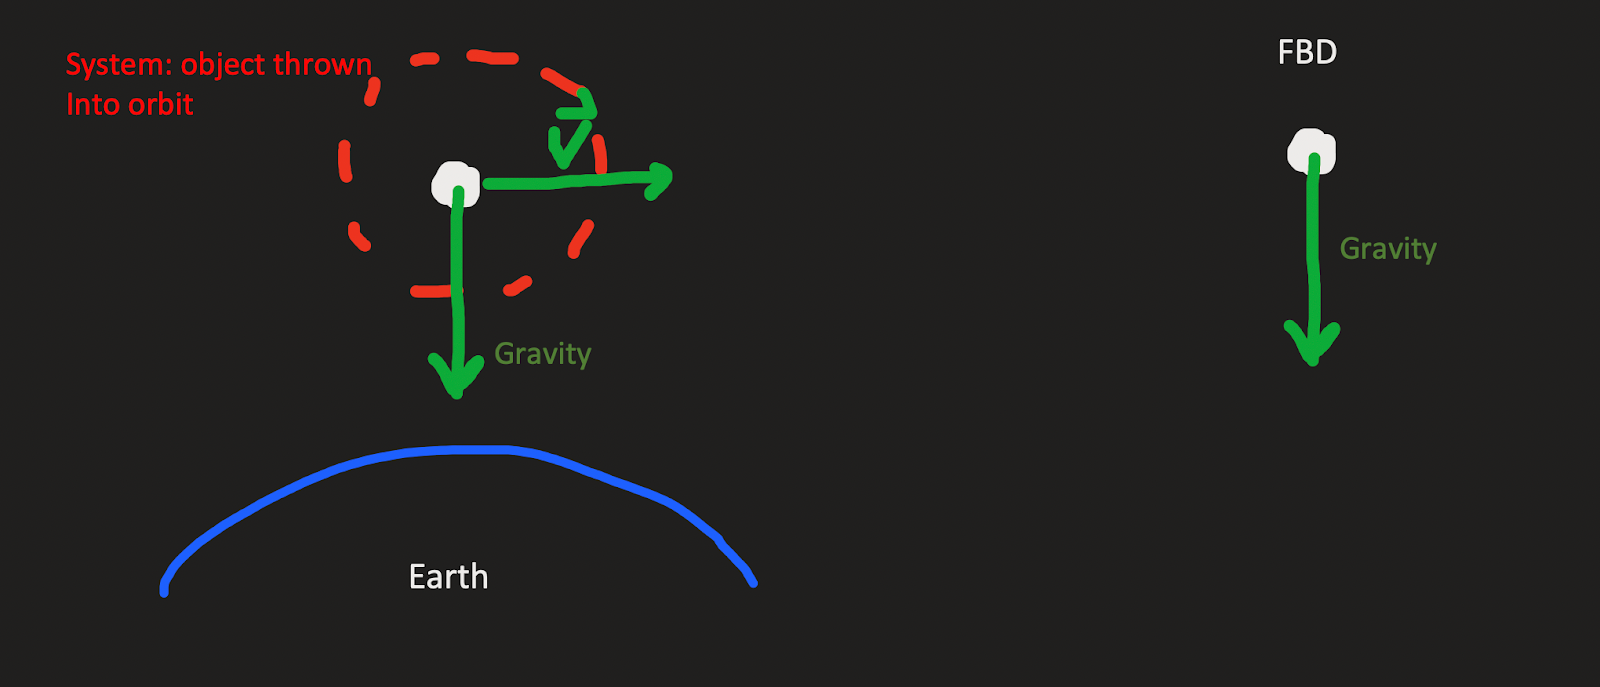

### ODEs

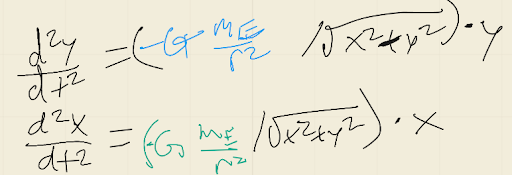

### Verification

#### Doesn't Go Through The Earth

First, we'll need to verify that, for all velocities, the object doesn't go through the Earth. This means that the object should never go below the Earth's surface. Technically, it's permissible for the object to be 0 meters from the Earth's surface, because that is the termination condition of the model. (ie. It's physically possible for the object to crash into the Earth, in which case the model stops.)

**Note:** Depending on MATLAB's mood, you may actually see some heights below the Earth's surface on the graph below. These are due to imprecisions in MATLAB's ODE45, and do not reflect errors in our model. To make them disappear (and therefore to generate more precise results), change the MaxStep on line 8 of simulate_launch.m to 10^2 or lower. This will, however, make the model take substantially longer to run. Adding an event function (which we have) is theoretically supposed to avoid exactly this situation, meaning that this phenomenon is a bug in MATLAB.

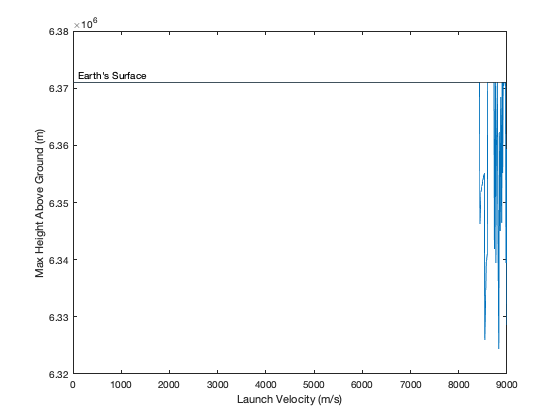

plot(velocities, min_heights);
yline(radius_earth)
ylabel("Max Height Above Ground (m)")
xlabel("Launch Velocity (m/s)")
text(100, radius_earth, "Earth's Surface", "VerticalAlignment", "bottom", "HorizontalAlignment", "left")

#### Magnitude of Velocity Changes

Next, we need to make sure our velocity is obeying the trajectories we expect. In particular, we expect that the magnitude of velocity to be inverseley correlated with the magnitude of position: When the object is farthest from Earth, it will have the most gravitational potential energy. Since the total energy of the object can't change, it's kinetic energy (which is directly correlated with velocity) must shrink. Conversely, when the object is closest to the Earth, it's kinetic energy (and therefore velocity) will be at a maximum because the gravitational potential energy will be at a minimum.

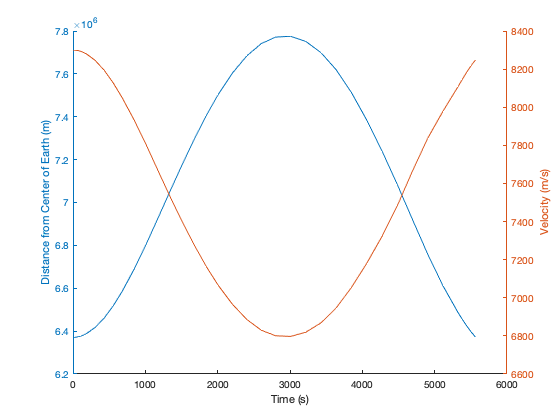

[T, P, V] = simulate_launch(timespan, [radius_earth + 1, 0, 0, 8300]);

clf; hold on;

yyaxis left;
plot(T, magnitude2d(P));
ylabel("Distance from Center of Earth (m)");

yyaxis right;
plot(T, magnitude2d(V));
ylabel("Velocity (m/s)");

xlabel("Time (s)");
hold off;

### Validation

In order to validate our model we compared the optimized orbital velocity we found to Earth’s measured escape velocity, and data on the minimum orbital velocity for an object in LEO. For an object to enter and temporarily stay in LEO, its velocity needs to stay in between these two velocities. When comparing data we wanted to ensure that our orbital velocity was greater than and close to the minimum orbital velocity data, but less than the data of Earth’s escape velocity. According to data we found in the links below, the minimum orbital velocity to keep an object in LEO is around 7,800 m/s and the escape velocity of the Earth is around 11,200 m/s. In our model and simulations we found that the optimal orbital velocity for an object thrown into space is approximately 8,000 m/s. Therefore, our models results line up with real world data/criteria. ([ESA](https://www.esa.int/ESA_Multimedia/Images/2020/03/Low_Earth_orbit), [Northwestern](https://www.qrg.northwestern.edu/projects/vss/docs/space-environment/2-whats-escape-velocity.html))

## Results

### Velocity

We found that the minimum launch velocity required to achive orbital heights was 8000 m/s (28,000 km/h,  17,895 mph, Mach 23). Slighly higher velocities simply resulted in higher heights, while much higher velocities eventually exceeded the escape velocity of the Earth and resulted in the object flying off in to space (not shown on graph).

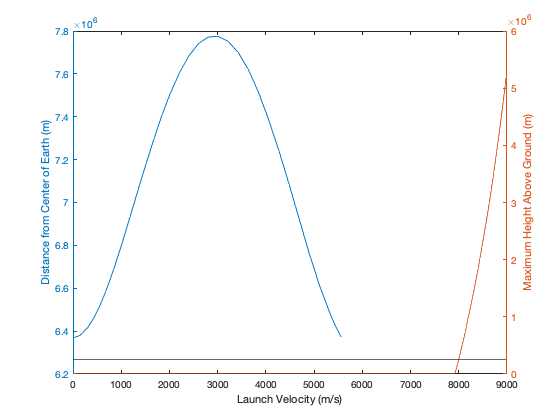

plot(velocities, max_heights - radius_earth);
yline(radius_orbit - radius_earth)
ylabel("Maximum Height Above Ground (m)")
xlabel("Launch Velocity (m/s)")

ylim([0 max_orbit_height])

Unrecognized function or variable 'max_orbit_height'.

x_lims = [7000, 9000];
xlim(x_lims)
text(x_lims(1) + 100, radius_orbit - radius_earth, "Orbit", "VerticalAlignment", "bottom", "HorizontalAlignment", "left")

### Maximum Energy

As expected, the maximum kinetic energy that an object acheived was strongly correlated with the maximum height that it reached. 

plot(0.5 * mass * (velocities .^ 2), max_heights - radius_earth);
yline(radius_orbit - radius_earth)
ylabel("Maximum Height Above Ground (m)")
xlabel("Maximum Energy (J)")
ylim([0 max_orbit_height])
x_lims = [150000000, 200000000];
xlim(x_lims)
text(mean(x_lims), radius_orbit - radius_earth, "Orbit", "VerticalAlignment", "bottom", "HorizontalAlignment", "center")

## Interpretation

We found that an object would need to be thrown at 8000 m/s to temporarily enter Low Earth Orbit. This is almost certainly not feasible, given that 8000 m/s is equivalent to 28,800 km/h (17,895 mph) or over Mach 23, which is *extremely* fast. It's nearly 180 *times* faster than the upper limit for how fast a human can throw something ([Popular Mechanics](https://www.popularmechanics.com/adventure/sports/a6063/how-the-105-mph-fastball-tests-the-limits-of-the-human-body/)). Consequently, we believe that Major League Baseball pitchers—and human throwers more broadly—lack promise as a space launch mechanism.

Our model—like all models—is not flawless. Most notably, we didn't attempt to model air resistance, which would play a significant role in the amout of energy required to reach orbit. Additionally, all of our trajectories were technically suborbital because the object would need to perform a [Hohmann transfer](https://en.wikipedia.org/wiki/Hohmann_transfer_orbit) to fully circularize and stabelize its orbit, which we didn't attempt to model. However, air resistance would certainly increase the initial launch velocity required to reach orbit (ie. would make it harder), so it wouldn't change our conclusion that human-powered spaceflight is impossible. The suborbital trajectories also didn't significantly affect our results because the Hohmann transfer wouldn't affect the initial launch velocity of the object—it would simply require the object to alter its velocity once it was in space, which was beyond the scope of both our question and our model. Therefore, we feel that neither of these shortcomings significantly affected the conclusions we drew from our model, although they would be excellent topics for future research or future iterations of this model. In particular, we think that another iteration of this model including air resistance would be an interesting complement to these results.

## Helper Functions

function res = magnitude2d(dat)
    res = sqrt(sum(dat .^ 2, 2));
end